# **demo14 of Im2mesh package**

demo14 - Generate mesh based on 2D contours

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

If you are using Im2mesh package in MATLAB, you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Initialize

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size (optional).

x = 250; y = 250; width = 300; height = 300;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function bounds2mesh use a mesh generator called MESH2D (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## 2D Matrix

Input is a 2d matrix with height value.

n = -1:0.1:1;
Z = peaks(n);   % Z is a 21-by-21 matrix containing the height values of
                % the surface with respect to the x-y plane.
size(Z)

ans =     21    21


Plot surface

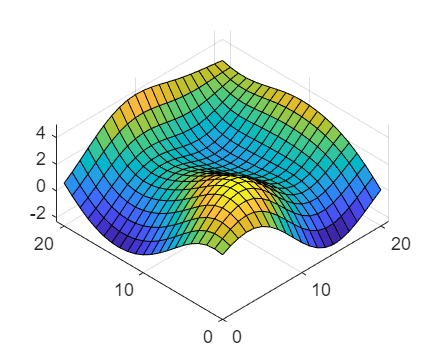

surf(Z);
view( -45 , 55 )

## 2D Contour

max(Z(:))

ans = 3.7403

min(Z(:))

ans = -2.2820

Define interested level and plot contour

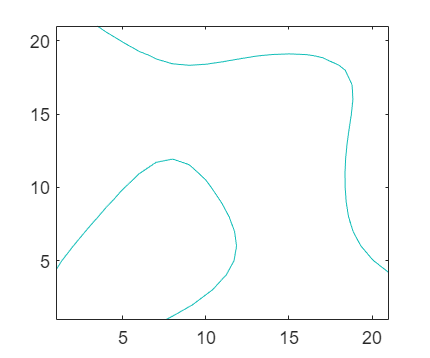

level = 1.5;    % interested level

contour(Z, [level,level]);

## Extract countour

Store vertices in the countour

% add (-inf) padding to Z
Z2 = padarray(Z,[1 1],-inf,'both');

C = contourc(Z2, [level,level]);

contourCell = {};   % a cell array for vertices in countours
k = 1;              % current column in C

while k < size(C,2)
    nv = C(2,k);           % number of vertices
    idx  = k+1 : k+nv;     % columns that hold the vertices
    xy = C(1:2,idx)';      % nv-by-2 array
    contourCell{end+1} = xy -1 ;    % -1 is used to removed padding

    k = k + nv + 1;       % jump to next header
end

Plot contourCell

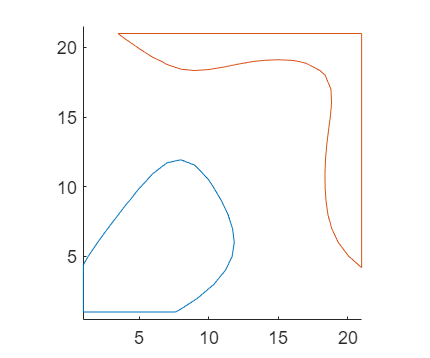

figure
hold on; axis equal
for i = 1: length(contourCell)
    plot( contourCell{i}(:,1), contourCell{i}(:,2) )
end
hold off

## Convert to polyshape

Convert contourCell to polyshape object

x_temp = [];
y_temp = [];

for i = 1: length(contourCell)
    x_temp = [ x_temp; NaN; contourCell{i}(:,1) ];
    y_temp = [ y_temp; NaN; contourCell{i}(:,2) ];
end

psIn = polyshape( x_temp, y_temp  );

Plot polyshape object

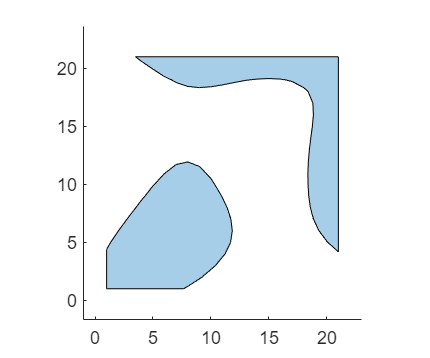

plot(psIn);
axis equal

## Create outer boundary

% outer boundary
xmin = 1;
xmax = 21;
ymin = 1;
ymax = 21;

Create polyshape for outer boundary

vertex = [xmin ymin; xmax ymin; xmax ymax; xmin ymax; xmin ymin];
psOB = polyshape(vertex);   % polyshape for outer boundary

Plot

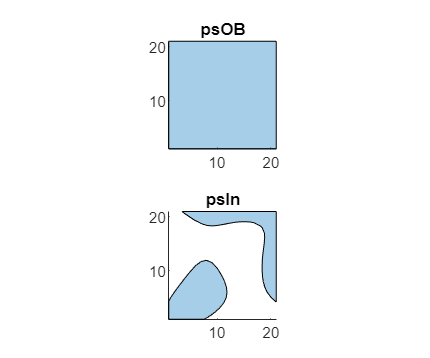

figure;
tiledlayout('flow')

nexttile
plot(psOB);
axis equal
title('psOB')
xlim([xmin xmax])
ylim([ymin ymax])

nexttile
plot(psIn);
axis equal
title('psIn')
xlim([xmin xmax])
ylim([ymin ymax])

## Boolean operation

psOB = subtract(psOB, psIn);

Plot

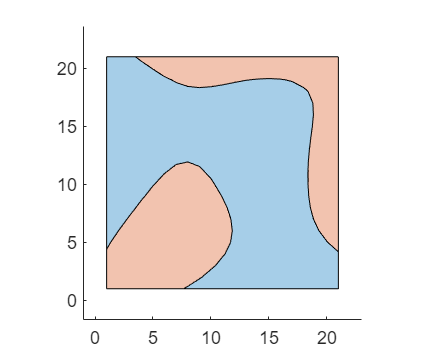

figure
hold on; axis equal
plot(psOB);
plot(psIn);
hold off

## Convert to polygonal boundaries

Convert to a nested cell array of polygonal boundaries

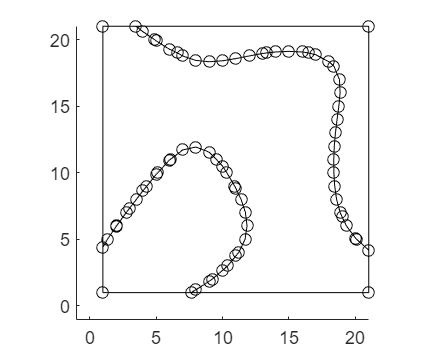

psCell = {psOB; psIn};              % a cell array of polyshape
bounds = polyshape2bound(psCell);   % a nested cell array of polygonal boundaries

tol_intersect = 1e-6;
bounds = addIntersectPnts( bounds, tol_intersect );

% plot polygons and show all vertices
plotBounds(bounds,false,'ko-')

## **Simplify boundaries**

We want to reduce the number of vertices.

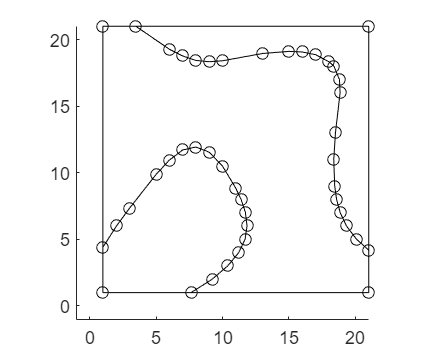

boundsCtrlP = getCtrlPnts( bounds );

% simplify polyline using Douglas-Peucker algorithm
tolerance = 0.05;
boundsReduced = simplifyBounds( boundsCtrlP, tolerance );

% show all vertices
plotBounds(boundsReduced,false,'ko-')

## Generate mesh via MESH2D

hmax = 500;
grad_limit = 0.25;
opt = [];
opt.disp = inf;     % silence verbosity

[vert,tria,tnum,vert2,tria2] = bounds2mesh( boundsReduced, hmax, grad_limit, opt );

Plot mesh

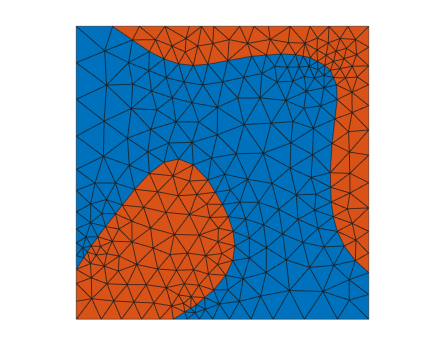

color = 1;
plotMeshes( vert,tria,tnum, color );

We can use function tricost to check mesh quality. 

`    tricost( vert, tria );`

See the link below for more examples.

[https://mjx888.github.io/others/Coutour2mesh/Coutour2mesh.html](https://mjx888.github.io/others/Coutour2mesh/Coutour2mesh.html)

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo